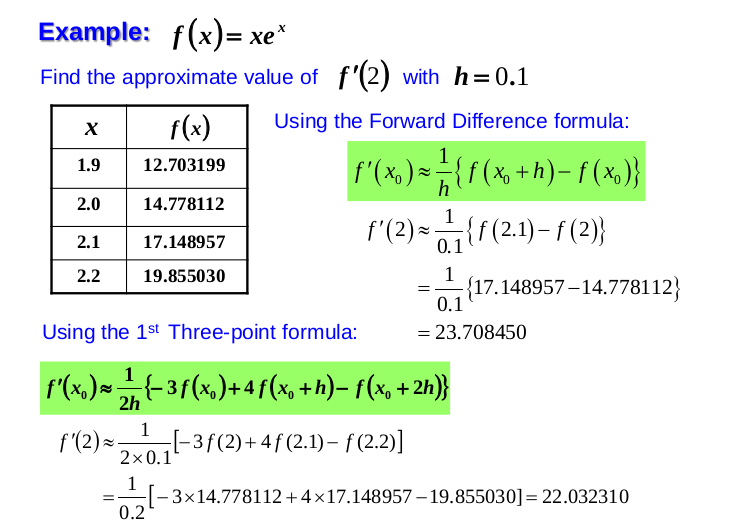

clear;clf
x = [1.9 2.0 2.1 2.2];
f = @(x)(x.*exp(x));
g = f(x)

g =    12.7032   14.7781   17.1490   19.8550



h = 0.1;
x0 = 2;

%Using the Forward Differrence formula
(1/h)*(f(x0+h)-f(x0))

ans = 23.7084


%Using the 1st Three-poinr formula
(1/(2*h))*(-3*f(x0)+4*f(h+x0)-f(x0+2*h))

ans = 22.0323


%Using the 2nd three-poing formula
(1/(h*2))*(f(x0+h)-f(x0-h))

ans = 22.2288

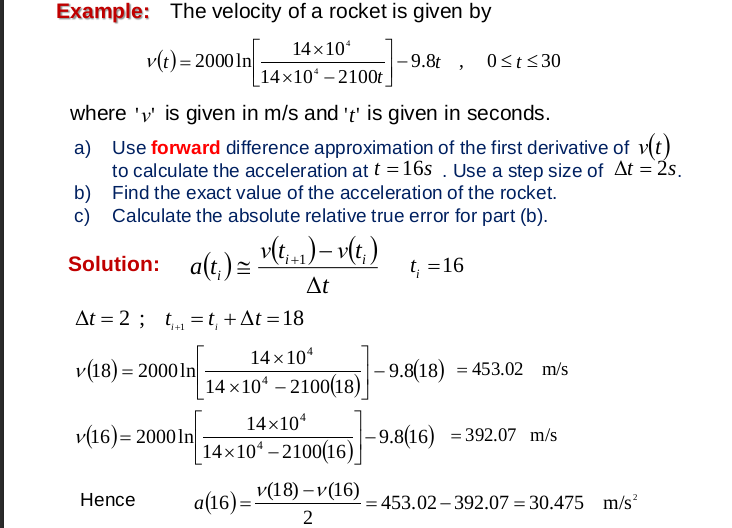

clear;clf

v = @(t)(2000*ln((14e4)/(14e4-2100*t))-9.8*t)

v = function_handle with value:
    @(t)(2000*ln((14e4)/(14e4-2100*t))-9.8*t)


h=2;

%use forward diff approximation
ApproximateValue = (v(18)-v(16))/h;

y = 0.3147

y = 0.2744

disp(['a) a(16) = ',num2str(ApproximateValue)])

a) a(16) = 30.4739




syms s t
f =(2000*ln((14e4)/(14e4-2100*t))-9.8*t)

$$y = \log\left(-\frac{140000}{2100\,t-140000}\right)$$

$$f = 2000\,\log\left(-\frac{140000}{2100\,t-140000}\right)-\frac{49\,t}{5}$$

df = diff(f);

TrueValue = subs(df,t,16)

$$TrueValue = \frac{2819}{95}$$

disp(['b) ',num2str(eval(TrueValue))])

b) 29.6737



epsilon = eval(abs((TrueValue-ApproximateValue)/TrueValue)*100)

epsilon = 2.6967

disp(['The absolute relative true error is ',num2str(epsilon),' %'])

The absolute relative true error is 2.6967 %





%use backward difference approximation
ApproximateValue = (v(16)-v(14))/h;

y = 0.2744

y = 0.2357

disp(['Approx: a(16) = ',num2str(ApproximateValue)])

Approx: a(16) = 28.9145


epsilon = eval(abs((TrueValue-ApproximateValue)/TrueValue)*100)

epsilon = 2.5584

disp(['The absolute relative true error is ',num2str(epsilon),' %'])

The absolute relative true error is 2.5584 %




%use central divided difference approximation
ApproximateValue = (v(18)-v(14))/(2*h);

y = 0.3147

y = 0.2357

disp(['Approx: a(16) = ',num2str(ApproximateValue)])

Approx: a(16) = 29.6942


epsilon = eval(abs((TrueValue-ApproximateValue)/TrueValue)*100)

epsilon = 0.0692

disp(['The absolute relative true error is ',num2str(epsilon),' %'])

The absolute relative true error is 0.069157 %


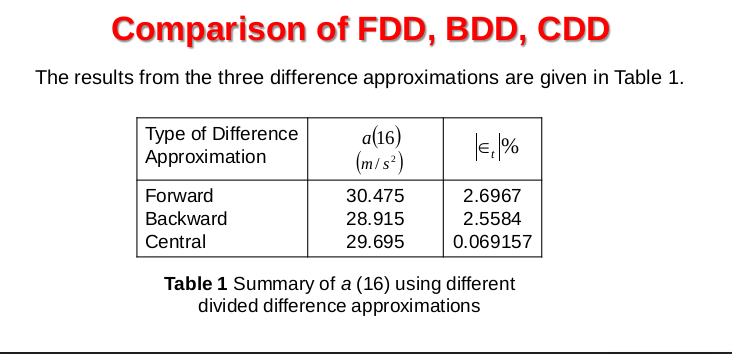

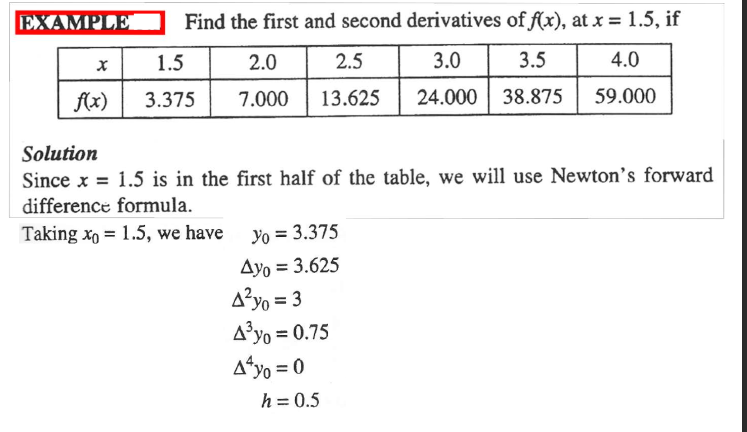

clear;clf
x = [1.5 2.0 2.5 3.0 3.5 4.0]

x =     1.5000    2.0000    2.5000    3.0000    3.5000    4.0000


y = [3.375 7.000 13.625 24.000 38.875 59.00]

y =     3.3750    7.0000   13.6250   24.0000   38.8750   59.0000


GaussTable(x,y)

ans =     1.5000    3.3750    3.6250    3.0000    0.7500         0         0
    2.0000    7.0000    6.6250    3.7500    0.7500         0         0
    2.5000   13.6250   10.3750    4.5000    0.7500         0         0
    3.0000   24.0000   14.8750    5.2500         0         0         0
    3.5000   38.8750   20.1250         0         0         0         0
    4.0000   59.0000         0         0         0         0         0


NewtonForwardDiff(x,y)

ans = 4.7500

NewtonForwardDiff2(x,y)

ans = 9

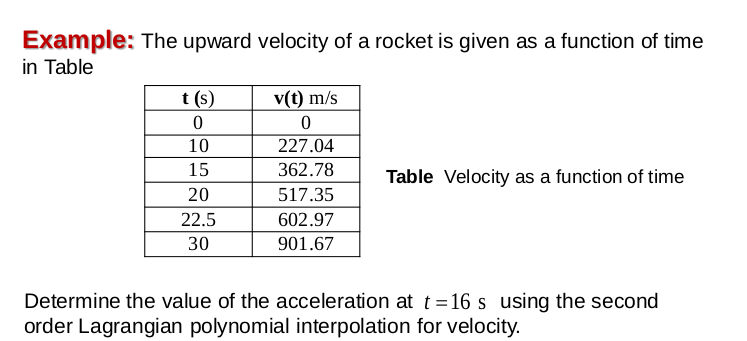

clear;clf ;
t = [10 15 20]

t =     10    15    20


v = [227.04 362.78 517.35 ]

v =   227.0400  362.7800  517.3500


disp(['Newton Method ',num2str(NewtonForwardDiff(t,v))])

Newton Method 25.265


t0=16;

(2*t0-(t(2)+t(3)))/((t(1)-t(2))*(t(1)-t(3)))*v(1)+...
(2*t0-(t(1)+t(3)))/((t(2)-t(1))*(t(2)-t(3)))*v(2)+...
(2*t0-(t(1)+t(2)))/((t(3)-t(1))*(t(3)-t(2)))*v(3)

ans = 29.7842

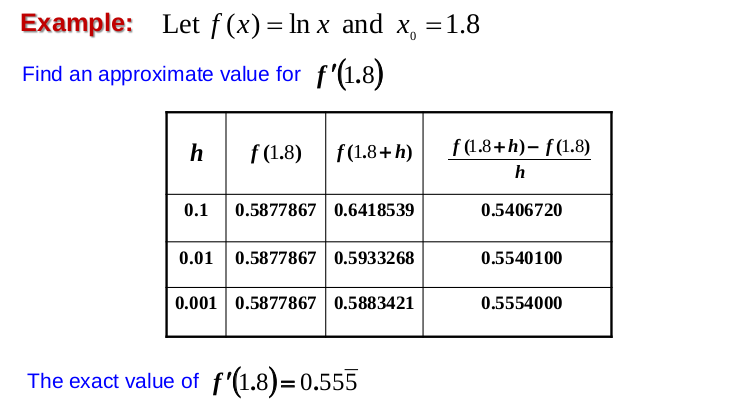  

clear;clf;
x = [1.8 1.9 2 2.1 2.2 2.3]

x =     1.8000    1.9000    2.0000    2.1000    2.2000    2.3000


y = @(x)(ln(x));
y = subs(y)

$$y = \log\left(x\right)$$

$$y = \left(\begin{array}{cccccc} \log\left(\frac{9}{5}\right) & \log\left(\frac{19}{10}\right) & \log\left(2\right) & \log\left(\frac{21}{10}\right) & \log\left(\frac{11}{5}\right) & \log\left(\frac{23}{10}\right) \end{array}\right)$$

disp('use newton')

use newton


NewtonForwardDiff(x,y)

ans = 0.5556


x0=1.8;
ans2 =(2*x0-(x(2)+x(3)))/((x(1)-x(2))*(x(1)-x(3)))*y(1)+...
(2*x0-(x(1)+x(3)))/((x(2)-x(1))*(x(2)-x(3)))*y(2)+...
(2*x0-(x(1)+x(2)))/((x(3)-x(1))*(x(3)-x(2)))*y(3);
disp('use lagrangian')

use lagrangian


eval(ans2)

ans = 0.5545